first read image and convert it to double presicion form:

image = im2double(imread('cameraman.tif'));
[n, m] = size(image);

now first decompose this matrix to svd form. then use first k components for estimate best rank-k matrix of initial image and calculate error by frobenuis norm:

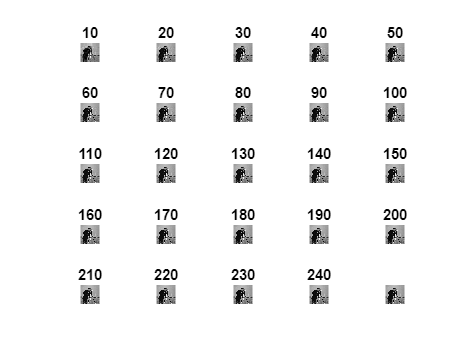

truncated_image = zeros(n, m);
error = zeros(200, 1);
[U, S, V] = svd(image);
k = linspace(1, 256, 256);
for i = 1:256
    truncated_image = truncated_image + U(:, i) * S(i, i) * V(:, i).';    
    if mod(i, 10) == 0
        subplot(5, 5, i/10);
        imshow(truncated_image);
        title(i);
    end    
    error(i) = norm(image - truncated_image, 'fro');
end  

imshow(truncated_image);

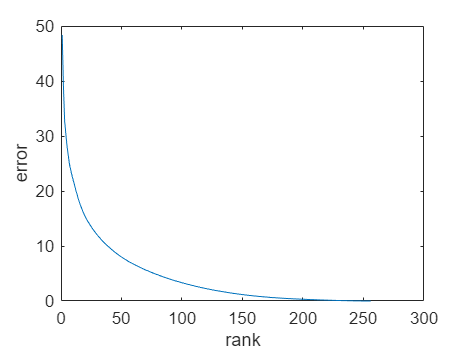


figure;
plot(k, error);
xlabel('rank');
ylabel('error');

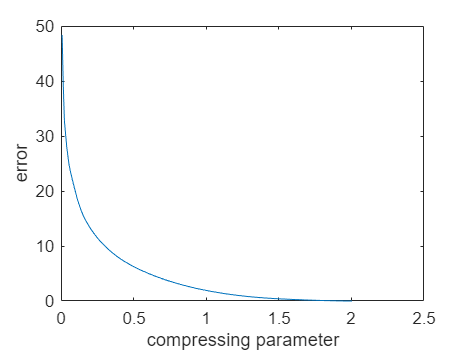


alpha = (256 * 2 + 1) / (256 * 256);

figure;
plot(alpha * k, error);
xlabel('compressing parameter');
ylabel('error');

now we must first normalize data then use svd:

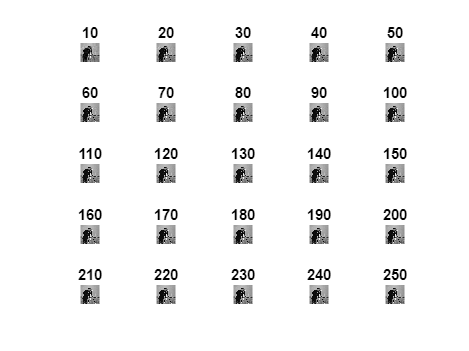

mean_image = 0;
[n, m] = size(image);
for i = 1:n
    for j = 1:m
        mean_image = mean_image + image(i, j);
    end    
end    
mean_image = mean_image / (n * m);
image = image - mean_image;
truncated_image = zeros(n, m) + mean_image;
error = zeros(200, 1);
[U, S, V] = svd(image);
image = image + mean_image;
k = linspace(1, 256, 256);
figure;
for i = 1:256
    truncated_image = truncated_image + U(:, i) * S(i, i) * V(:, i).';
    if mod(i, 10) == 0
        subplot(5, 5, i/10);
        imshow(truncated_image);
        title(i);
    end 
    error(i) = norm(image - truncated_image, 'fro');
end  

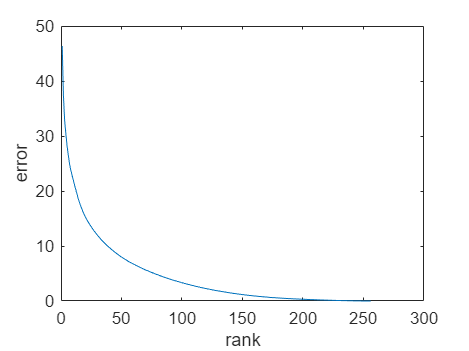


figure;
plot(k, error);
xlabel('rank');
ylabel('error');

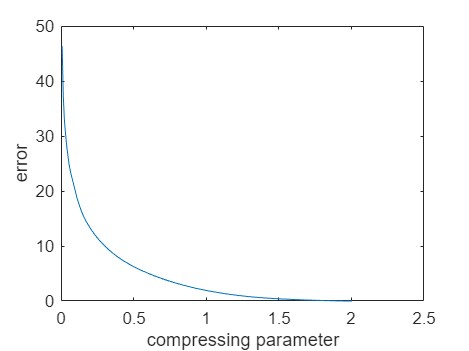


alpha = (256 * 2 + 1) / (256 * 256);

figure;
plot(alpha * k, error);
xlabel('compressing parameter');
ylabel('error');

first load data:

file = load('EEGdata.mat');
noisy_data = file.Xnoise;
pure_data = file.Xorg;

then use svd decompostion on noisy data and calculate error for every estimation and plot error versus rank:

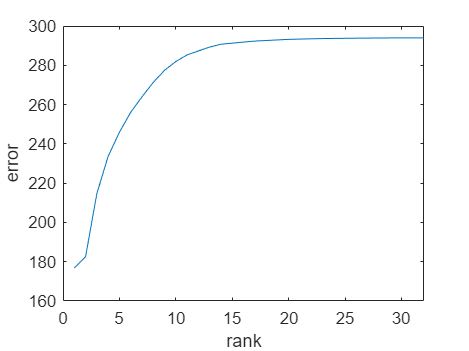

[U, S, V] = svd(noisy_data);
k_rank_approximation = zeros(32, 5000);
error = zeros(32, 1);
k = linspace(1, 32, 32);
for i = 1:32
    k_rank_approximation = k_rank_approximation + U(:, i) * S(i, i) * V(:, i).';   
    error(i) = norm(pure_data - k_rank_approximation, 'fro');
end    

figure;
plot(k, error);
xlabel('rank');
ylabel('error');

as you can see from graph, error increases strictly by increament in rank, so the best approximation for number of sources is one.

first load data:

load('PCAdata.mat');

then plot them by scatter3 function:

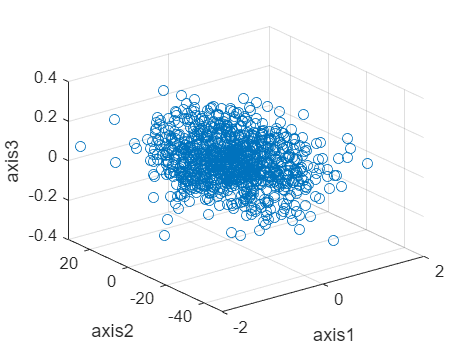

figure;
scatter3(PCAdata(1, :), PCAdata(2, :), PCAdata(3, :));
xlabel('axis1');
ylabel('axis2');
zlabel('axis3');


initial_var1 = var(PCAdata(1, :));
initial_var2 = var(PCAdata(2, :));
initial_var3 = var(PCAdata(3, :));
fprintf('variance in first axis is %i', initial_var1);

variance in first axis is 2.291722e-01

fprintf('variance in second axis is %i', initial_var2);

variance in second axis is 9.234085e+01

fprintf('variance in third axis is %i', initial_var3);

variance in third axis is 9.581750e-03

now shift mean of data to zero and variance to one(normalize):

mean_vector = zeros(3, 1);
for i = 1:3
    mean_vector(i) = mean(PCAdata(i, :));
    PCAdata(i, :) = PCAdata(i, :) - mean_vector(i);
    PCAdata(i, :) = PCAdata(i, :) / sqrt(var(PCAdata(i, :)));
end

now use svd decompostion. first two left singular vectors are our principal components:

[U, S, V] = svd(PCAdata);
PCA1 = U(:, 1);
PCA2 = U(:, 2);

now we must project data on these axes use inner product:

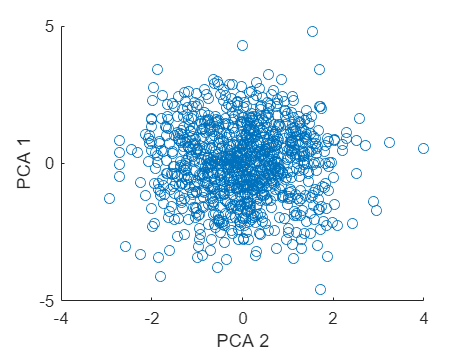

[n, m] = size(PCAdata);
pc1 = zeros(m, 1);
pc2 = zeros(m, 1);
   
pc1 = PCA1.' * PCAdata;
pc2 = PCA2.' * PCAdata;

figure;
scatter(pc2, pc1);
xlabel('PCA 2');
ylabel('PCA 1');


var1 = var(pc1);
fprintf('variance in first principal component is %i', var1);

variance in first principal component is 1.865477e+00

var2 = var(pc2);
fprintf('variance in second principal component is %i', var2);

variance in second principal component is 1.025294e+00

now use matlab built-in function for PCA:

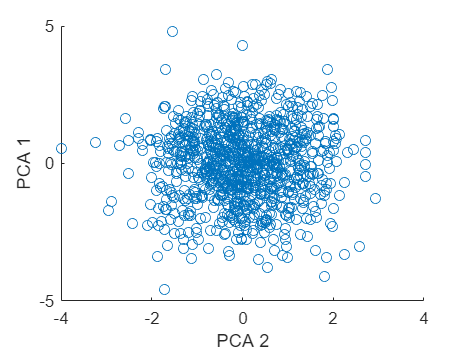

[coeff, score, latent] = pca(PCAdata.');

[n, m] = size(PCAdata);
PC1 = zeros(m, 1);
PC2 = zeros(m, 1);
   
PC1 = coeff(:, 1).' * PCAdata;
PC2 = coeff(:, 2).' * PCAdata;

figure;
scatter(PC2, PC1);
xlabel('PCA 2');
ylabel('PCA 1');


var_built_in1 = var(PC1);
fprintf('variance in first principal component is %i', var_built_in1);

variance in first principal component is 1.865477e+00

var_built_in2 = var(PC2);
fprintf('variance in second principal component is %i', var_built_in2);

variance in second principal component is 1.025294e+00

first load data and decompose matrix to svd form:

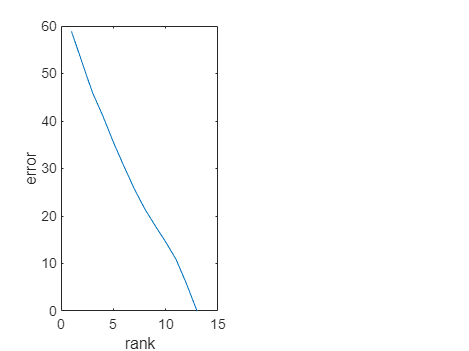

data = load('house_dataset.mat');
houseInputs = data.houseInputs.';
houseTargets = data.houseTargets.';
[n, m] = size(houseInputs);
for i = 1:m
    houseInputs(:, i) = houseInputs(:, i) - mean(houseInputs(:, i));
    houseInputs(:, i) = houseInputs(:, i) / sqrt(var(houseInputs(:, i)));
end    
[U, S, V] = svd(houseInputs, 'econ');
error = zeros(m, 1);
truncated_data = zeros(n, m);
for i = 1:m
    truncated_data = truncated_data + U(:, i) * S(i, i) * V(:, i).';
    error(i) = norm(truncated_data - houseInputs, 'fro');
end        

k = linspace(1, m, m);
subplot(1, 2, 1)
plot(k, error);
xlabel('rank');
ylabel('error');

first plot price versus features:

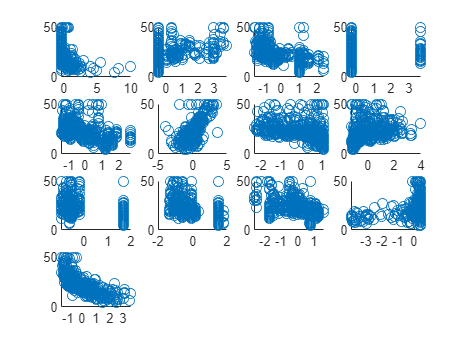

for i = 1:13
    subplot(4, 4, floor(i / 4) * 4 + mod(i, 4))
    scatter(houseInputs(:, i), houseTargets);
end    

in above graphs for example in fifth one, we see a increasing graph, thirtheenth one is non-increasing, in third , fourth , nineth, tenth, twelveth we have two clusters.  

from previous result for error versus rank, we can choose first three components.

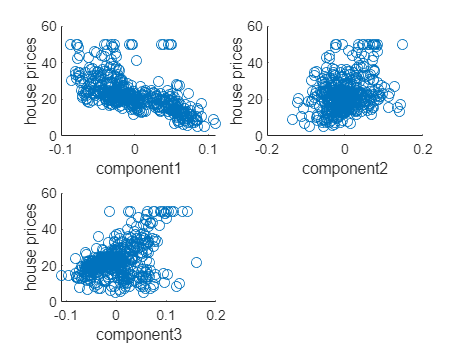

component1 = U(:, 1);
component2 = U(:, 2);
component3 = U(:, 3);

figure;
subplot(2, 2, 1)
scatter(component1, houseTargets)
xlabel('component1')
ylabel('house prices');

subplot(2, 2, 2)
scatter(component2, houseTargets)
xlabel('component2')
ylabel('house prices');

subplot(2, 2, 3)
scatter(component3, houseTargets)
xlabel('component3')
ylabel('house prices');

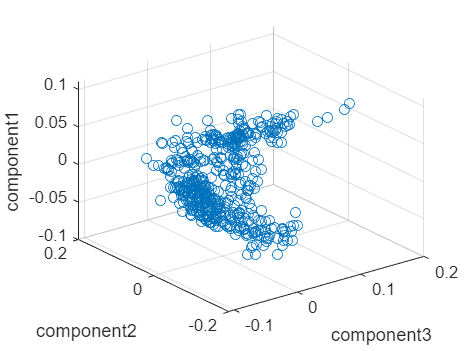


figure;
scatter3(component3, component2, component1);
xlabel('component3');
ylabel('component2');
zlabel('component1');

in first graph we see house prices almost decrease with increament in component1.also we have two clusters in axis x. in second graph we can say estimatly house prices don't change with change in component2 and data are compressed in center. third graph is also similar to second one.

in 3d graph we see in plane component1-component2 we have almost two clusters.

one property which we can understand from right singular matrix is correlation between features. plot every new feature against initial features. every data in these graphs, shows the dependency of new feature to that initial feature.

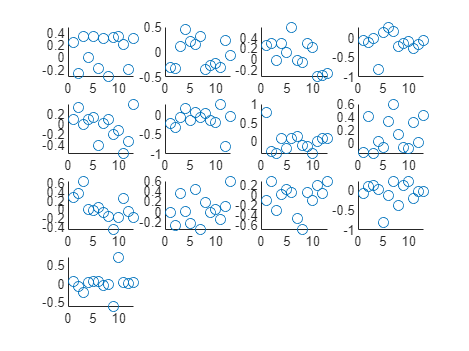

k = linspace(1, 13, 13);
figure;
for i = 1:13
    subplot(4, 4, floor(i / 4) * 4 + mod(i, 4))
    scatter(k, V(:, i));
end    